# `Rotation and Transformation Matricies`

`demonstrated`

`By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`For tutoring purposes | Entry level Robotics | 11/23/2022`

clc; clear; close all

### `Motivation `

`Express a frame of refrence, orientation and position, with respect to some origin, or space, frame`

### `Background `

`Some details are provided for convenience. Familiarity with these topics is reccomended.`

`Matricies`

`Configuration Space: Chapter 2 of Modern Robotics, by Kevin Lynch and Frank C Park`

    A. Degrees of Freedom 

            1. Grublers formula

    B.  Implicit vs Explicit representations 

            1. Explicit representations - use one variable for each degree of freedom, DOF, to represent a state

               a. Suffer from singularities, use minimal coordinates

               b. Singularities occur during a discontinuity or unproportionate change in coordinate representation where the associated movement is continuous

               c. Latitude and Longitude form an Explicit represenation, but suffer from a singularity at and near the poles

            2. Implicit representations - use a space embedded in a higher dimension subject to constraints

               a. Avoid singularities at the cost of storing more numbers for formatting purposes

    C. Topology vs coordinate representation 

            1. topological equivelancy 

### `Visualization Strategy`

`quiver3(`[`X`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_11a9c81a-dd8f-4048-985c-69334ea95510)`,`[`Y`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_532d51a4-2dc0-4591-a19a-382b5f398cbe)`,`[`Z`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_98c7fca0-6797-4af4-a55d-badb1396f150)`,`[`U`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_2fb36db1-5bec-47f2-905b-0ae4e2d7e057)`,`[`V`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_bce4f7d6-f000-4508-bdec-e07784eba424)`,`[`W`](https://www.mathworks.com/help/matlab/ref/quiver3.html#mw_6ffdb680-aaf3-4e07-83de-7fa71c2fae0b)`) plots arrows with directional components U, V, and W at the Cartesian coordinates specified by X, Y, and Z`

### `Matrix row and column extraction`

- `matrix rows or columns in a matrix A can be extracted by multiplying A by some other matrix`

`multiplying matrix A, 2x2 with [1 0]'`

A = [1 2 3; 4 5 6; 7 8 9];
column = [1 0 0]';
A*column %extracting the column requires postmultiplying A and a 3x1 matrix 

ans =      1
     4
     7


# **Rotation Matricies**

Similarly, axis can be extracted and rotated with rotation matricies

    An orientation of a new frame, expressed in a space frame can be represented with three unit vectors.This Implicit representation implies constraints requiring the x and y axis to be 90 degrees from eachother and the z axis being orthoganal to the xy plane. 

Where a rotation matrix can be written as a set of three vectors where the new axis are defined by each vector, X Y Z, or expressed in terms of an angle

About the Z axis

syms angle; rotz = rotZ(angle)

$$rotz = \left(\begin{array}{ccc} \cos\left(\text{angle}\right) & -\sin\left(\text{angle}\right) & 0\\ \sin\left(\text{angle}\right) & \cos\left(\text{angle}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

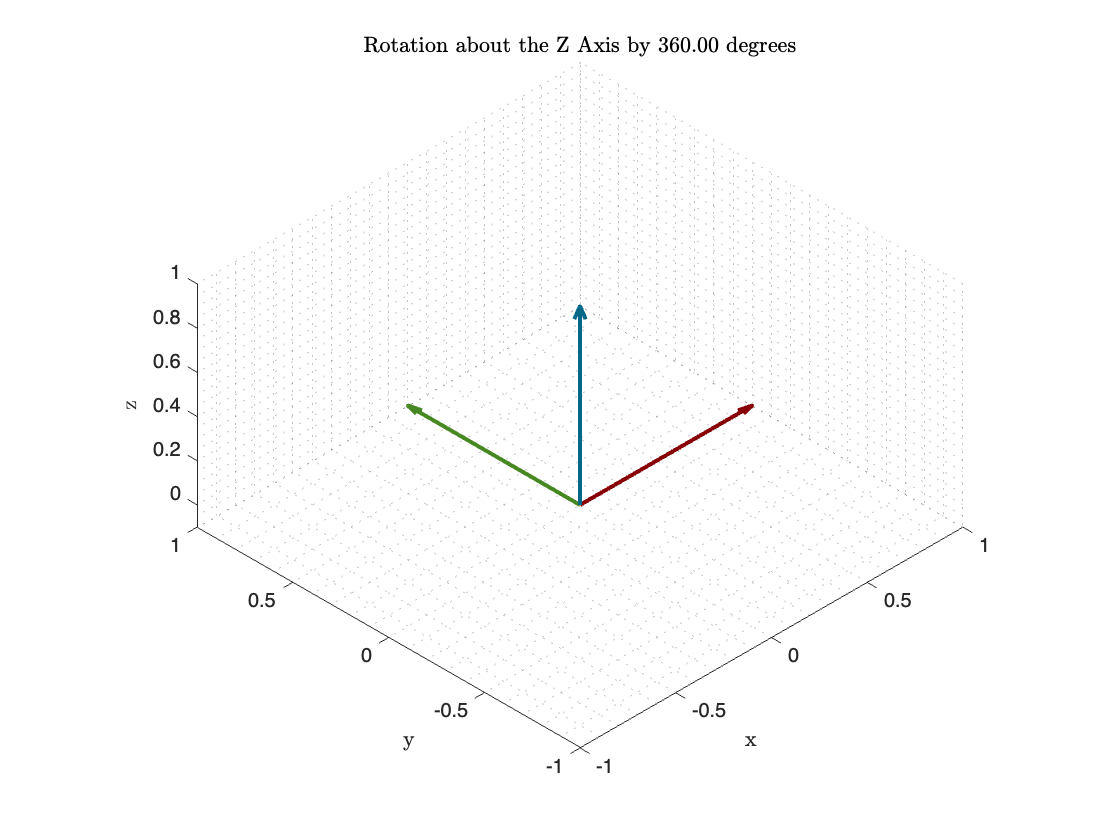

%Space Frame axis
X = [1 0 0]'; Y = [0 1 0]'; Z = [0 0 1]'; 
location = [0 0 0];
axisLimits = initializeAxisLimits();
endAngle = 360;
for i = 0:8:endAngle
    hold on
    % New axis
    orientation = [X Y Z]*rotZ(i*pi/180);
    % New axis colors
    darkness = i/endAngle/1.15;
    % Draw the space frame axis
    axisLimits = drawAxis(location,eye(3),0,axisLimits);
    % Draw the new axis
    axisLimits = drawAxis(location,orientation,darkness,axisLimits);
    % Include the current angle in the title
    title(sprintf('Rotation about the Z Axis by %0.2f degrees',i),'Interpreter','Latex');
    xlim([-1 1]); ylim([-1 1]); zlim([-0.1 1]); grid minor
    saveFrame('animation.gif',i)
    if i< endAngle
        clf
    end 
end

Similarly, Rotations about x and y can be described  by

rotx = rotX(angle)

$$rotx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\text{angle}\right) & -\sin\left(\text{angle}\right)\\ 0 & \sin\left(\text{angle}\right) & \cos\left(\text{angle}\right) \end{array}\right)$$

roty = rotY(angle)

$$roty = \left(\begin{array}{ccc} \cos\left(\text{angle}\right) & 0 & \sin\left(\text{angle}\right)\\ 0 & 1 & 0\\ -\sin\left(\text{angle}\right) & 0 & \cos\left(\text{angle}\right) \end{array}\right)$$

Furthermore, a rotation about an arbitrary axis can be described with Rodrigues Formula

# Transformation Matricies

translation and change in rotation 

T = [R 0 ; 0 1]

A tranformation matrix conveys a rotation and translation

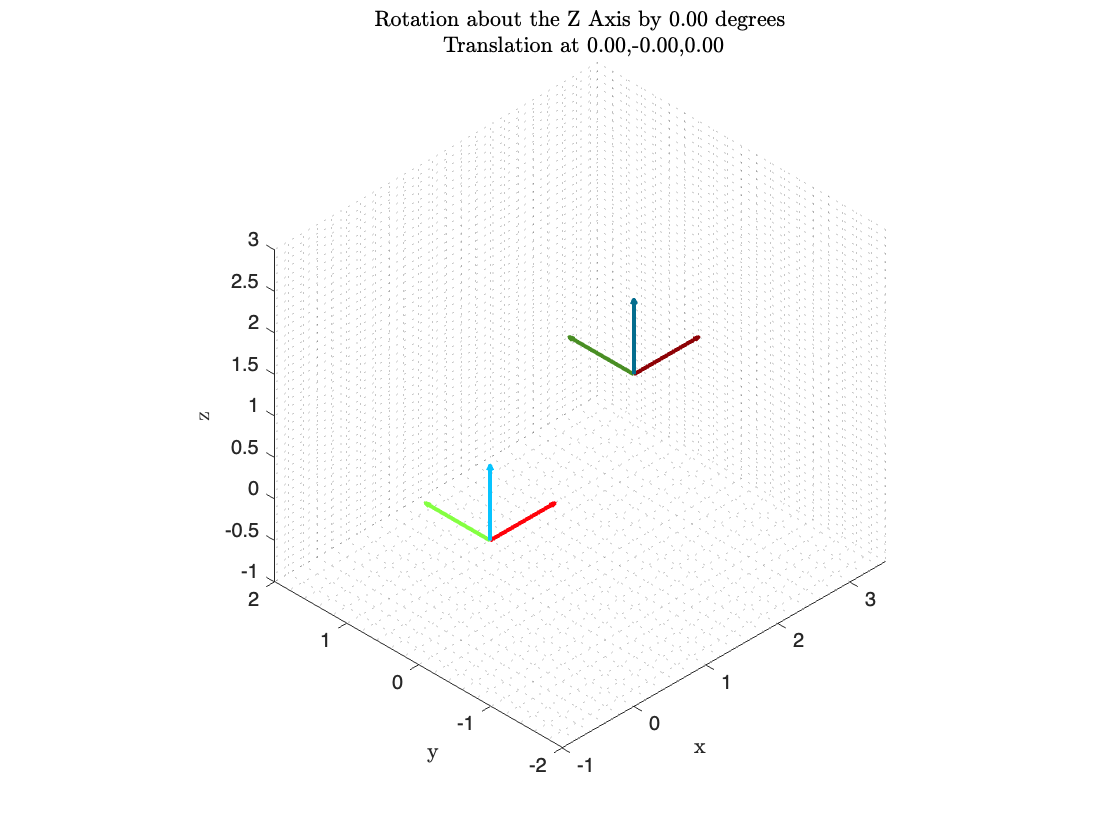

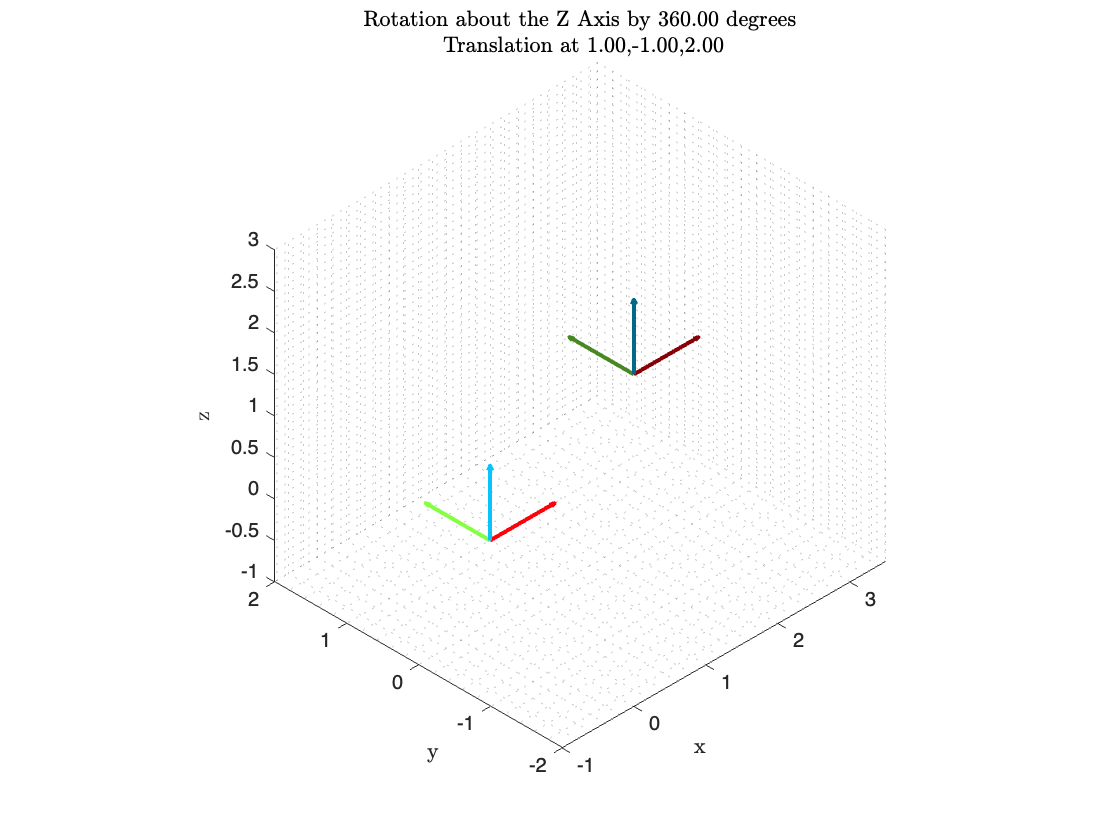

axis = [0 0 1];

%Space Frame axis
X = [1 0 0]'; Y = [0 1 0]'; Z = [0 0 1]'; 
locationStart = [0 0 0];
locationEnd = [1 -1 2];

axisLimits = initializeAxisLimits();
endAngle = 360;

grid minor
for i = 0:8:endAngle
        grid minor
        hold on
        % New axis
        orientation = [X Y Z]*rotZ(i*pi/180);
        % New axis colors
        darkness = i/endAngle/1.15;
        % Draw the space frame axis
        axisLimits = drawAxis(locationStart,eye(3),0,axisLimits);
        % Draw the End axis
        drawAxis(locationEnd,[X Y Z]*rotZ(endAngle*pi/180),.8,axisLimits);   %location,orientation,darkness,axisLimits)
        % Draw the new axis
        locationProgress = i/endAngle*locationEnd;
        axisLimits = drawAxis(locationProgress,orientation,darkness,axisLimits);
%         % Draw the rotation axis 
%         hold on
%         l = location;
%         quiver3([l(1) -l(1)],[l(2) -l(2)],[l(3) -l(3)],[axis(1) -axis(1)],[axis(2) -axis(2)],[axis(3) -axis(3)],"--"), hold on
        % Include the current angle in the title
        lp(1) = locationProgress(1); lp(2) = locationProgress(2); lp(3) = locationProgress(3);
        title(sprintf('Rotation about the Z Axis by %0.2f degrees\n Translation at %0.2f,%0.2f,%0.2f',i,lp(1),lp(2),lp(3)),'Interpreter','Latex');
        xlim([-1 3.5]); ylim([-2 2]); zlim([-1 3]); 
        grid minor
        saveFrame('animation.gif',i)
        if i< endAngle
            clf
        end 
    end

# Functions

Draw Axis Function

function axisLimits = drawAxis(location,orientation,darkness,axisLimits)
f = 1+darkness; %Darkness should be from 0 to 1
% color = ['D95D39','5A0B4D','BAFF29']; HEX
    color(1,:) = [182, 2, 8]/182/f;   % red
    color(2,:) = [59, 114, 29]/114/f; % green
    color(3,:) = [4, 110, 143]/143/f; % blue

%plotting 3 vectors
    Isometric = [-45 35.264];
    hold on
    for i = 1:1:3
        vec = orientation(:,i);
        quiver3(location(1),location(2),location(3),vec(1),vec(2),vec(3),'LineWidth',2,'Color',color(i,:));
        %scatter3(vec(1),vec(2),vec(3),'Color',color(i,:),'LineWidth',0.15); %helps set the axis limits
        axisLimits = checkAxisLimits(vec,axisLimits);
    end 
    hold off
%Viewing and Plot Settings
    axis equal
    view(Isometric)
    %xl = [-0.1 1.1]; yl = [-0.1 1.1]; zl = [-0.1 1.1];
    %xlim(xl); ylim(yl); zlim(zl);
    grid minor
    xlabel('x', 'Interpreter', 'Latex'),ylabel('y', 'Interpreter', 'Latex'),zlabel('z', 'Interpreter', 'Latex')
end 
%set(gca,'Color',background)

`Axis Limits Functions`

function axisLimits = initializeAxisLimits()
    %Initialize axis limits
    axisLimits.xmin=-0.01; axisLimits.xmax=0.1; axisLimits.ymin=-0.01; axisLimits.ymax=0.1; axisLimits.zmin=-0.01; axisLimits.zmax=0.1;
end 
function [axisLimits] = checkAxisLimits(p_now,axisLimits);
x = p_now(1); y = p_now(2) ; z = p_now(3);
%Check the current point in 3D space
%Goal of the function is to get the maximum and minimum x y z for all time
%For setting axis limits
        if x > axisLimits.xmax
            axisLimits.xmax = x; 
        elseif x < axisLimits.xmin
            axisLimits.xmin = x; 
        end 
        if y > axisLimits.ymax 
            axisLimits.ymax = y; 
        elseif y < axisLimits.ymin
            axisLimits.ymin = y; 
        end 
        if z > axisLimits.zmax
            axisLimits.zmax = z;
        elseif z < axisLimits.zmin
            axisLimits.zmin = z; 
        end 
end 

function [axisLimits] = increaseAxisLimits(axisLimits,inc)
%Simply to shorten the code above
    axisLimits.xmin = inc*axisLimits.xmin; 
    axisLimits.xmax = inc*axisLimits.xmax; 
    axisLimits.ymin = inc*axisLimits.ymin;
    axisLimits.ymax = inc*axisLimits.ymax;
    axisLimits.zmin = inc*axisLimits.zmin;
    axisLimits.zmax = inc*axisLimits.zmax;
end 

function setAxisLimits(axisLimits)
    xl = [axisLimits.xmin axisLimits.xmax]; yl = [axisLimits.ymin axisLimits.ymax]; zl = [axisLimits.zmin axisLimits.zmax];
    xlim(xl); ylim(yl); zlim(zl);
end 


`Save Gif Function `

function saveFrame(filename,t)
%SAVE FRAME
        % delay
        pause(0.005)
        % saving the figure
        frame = getframe(gcf);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if t == 0 %create the file if t is 1
          imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
          %Could write a preprogrammed image here
        end 
        if t > 1 %just append to the file if its not t = 1
        imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',0.05)%,...
        %'DelayTime',0.1);
        end 
end 

`Script Specific Functions `

function axisLimits = formatPlot(background)
    %Formatting the plot
    set(gca,'Color',background)
    axisLimits = initializeAxisLimits();
end 

#### `Animate rodrigues Rotation`

function animateRotation(axis,endAngle)
    %Space Frame axis
    X = [1 0 0]'; Y = [0 1 0]'; Z = [0 0 1]'; 
    location = [0 0 0];
    axisLimits = initializeAxisLimits();
    endAngle = -360;
    for i = 0:6:endAngle
        hold on
        % New axis
        orientation = [X Y Z]*rot(axis,i*pi/180);
        % New axis colors
        darkness = i/endAngle/1.15;
        % Draw the space frame axis
        axisLimits = drawAxis(location,eye(3),0,axisLimits);
        % Draw the new axis
        axisLimits = drawAxis(location,orientation,darkness,axisLimits);
        % Draw the rotation axis 
        hold on
        l = location;
        quiver3([l(1) -l(1)],[l(2) -l(2)],[l(3) -l(3)],[axis(1) -axis(1)],[axis(2) -axis(2)],[axis(3) -axis(3)],"--"), hold on
        % Include the current angle in the title
        title(sprintf('Rotation about the Z Axis by %0.2f degrees',i),'Interpreter','Latex');
        xlim([-1 1]); ylim([-1 1]); zlim([-1 1]); 
        grid minor
        saveFrame('animation.gif',i)
        if i< endAngle
            clf
        end 
    end
end 

# `Functions`

`Create a Skew Symmetric Matrix`

function so3mat = VecToso3(omg)
% useful for chapter 3: rigid-body motions
% takes a 3-vector (angular velocity)
% returns the skew symmetric matrix in so(3)
    so3mat = [0, -omg(3), omg(2); omg(3), 0, -omg(1); -omg(2), omg(1), 0];
end
function rot = rotX(a)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot = [1,0,0;0,cos(a),-sin(a);0,sin(a),cos(a)];
end

function rot = rotY(b)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Y axis
    rot = [cos(b),0,sin(b);0,1,0;-sin(b),0,cos(b)];
end

function rot = rotZ(g)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot= [cos(g),-sin(g),0;sin(g),cos(g),0;0,0,1];
end

function rot = rot(wHat,theta)
% useful for rigid-body motions
% takes a unit vector and an angle of rotation (radians)
% returns the corresponding rotatin matrix 3 by 3
    w1 = wHat(1); w2=wHat(2); w3=wHat(3);
    c = cos(theta); s=sin(theta); omc=(1-c);
    row1 = [c+w1^2*omc w1*w2*omc*-w3*s w1*w3*omc*w2*s];
    row2 = [w1*w2*omc+w3*s c+w2^2*omc w2*w3*omc-w1*s];
    row3 = [w1*w3*omc-w2*s w2*w3*omc+w1*s c+w3^2*omc];
    rot = [row1;row2;row3];
end